# Synthesis of the connection of three pipes

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_3_pipes_height_38um_pulse_5s_rectangular_tetrazine_Design_1');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_3_pipes_height_38um_pulse_5s_rectangular_tetrazine_Design_1



Parameters

p0=0.44146 mbar


c_Tartrazine_ini = 0.0845

c_max = 0.0845

mu = 9.9792e-04

D_coeff = 4.9000e-10

Q_inlet_CNN=2.2 uL/min



% Load a video file for image processing
videoFileName = fullfile(pwd, 'CNN_Outlet_500_ms (1).mp4');
videoFileName = fullfile(pwd, 'CNN_Outlet_1_s (1).mp4');
videoFileName = fullfile(pwd, 'CNN_Outlet_1_5_s (1).mp4');
videoObject = VideoReader(videoFileName);

% Check if the video file exists
if ~isfile(videoFileName)
    error('Video file does not exist. Please check the file name and path.');
end

% Get video properties
frameRate = videoObject.FrameRate

frameRate = 2

totalFrames = floor(videoObject.Duration * frameRate);

fprintf('Total number of frames: %d\n', totalFrames);

Total number of frames: 84



% Define start and end time (in seconds)
startTime = 12;  % e.g., start at 4 seconds
endTime   = 36; % e.g., end at 10 seconds

% Set the video reader to the start time
videoObject.CurrentTime = startTime;

% Initialize cell array to store frames
segmentedFrames = {}; 
frameIdx = 1;

% Read frames between startTime and endTime
while hasFrame(videoObject) && videoObject.CurrentTime <= endTime
    frame = readFrame(videoObject);
    segmentedFrames{frameIdx} = frame;  %#ok<SAGROW> store current frame
    frameIdx = frameIdx + 1;
end

fprintf('Stored %d frames between %.2f s and %.2f s\n', numel(segmentedFrames), startTime, endTime);

Stored 49 frames between 12.00 s and 36.00 s




% Create a VideoWriter object to save the processed frames
outputVideoFileName = fullfile(pwd, ['Processed_' videoObject.Name]); % Prepend "processed_" to the original video name
outputVideo = VideoWriter(outputVideoFileName, 'MPEG-4'); % Specify the video format
outputVideo.FrameRate = videoObject.FrameRate; % Set the frame rate
open(outputVideo); % Open the video file for writing

% Write the segmented frames to the video file
for j = 1:length(segmentedFrames)
    writeVideo(outputVideo, uint8(segmentedFrames{j})); % Convert to uint8 and write the frame
end

close(outputVideo); % Close the video file
fprintf('Processed video saved as: %s\n', outputVideoFileName);


### Reading at the CNN outlet

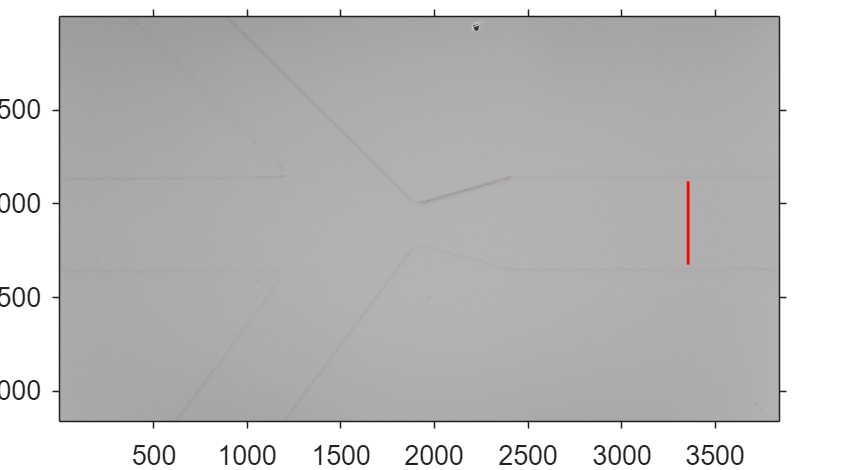

% Predefined coordinates for the line and pulse duration 500 ms
xCoords = [3355, 3355]; % X coordinates
yCoords = [937, 1341]; % Y coordinates

% Predefined coordinates for the line and pulse duration 1 s
xCoords = [3355, 3355]; % X coordinates
yCoords = [1254, 849]; % Y coordinates

% Predefined coordinates for the line and pulse duration 1.5 s
xCoords = [3355, 3355]; % X coordinates
yCoords = [1324, 879]; % Y coordinates

% Plot the first frame of segmentedFrames with axes
if ~isempty(segmentedFrames)
    figure; % Create a new figure window
    imshow(segmentedFrames{1}); % Display the first frame
    axis on; % Turn on the axes
    xlabel('Pixels (X)',Interpreter='latex'); % Label for X-axis
    ylabel('Pixels (Y)',Interpreter='latex'); % Label for Y-axis    
    
    % Hold the current plot to overlay the line
    hold on;
    plot(xCoords, yCoords, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    hold off;
    set(gca,"FontSize",fontsize)
else
    warning('No frames available to display.');
end

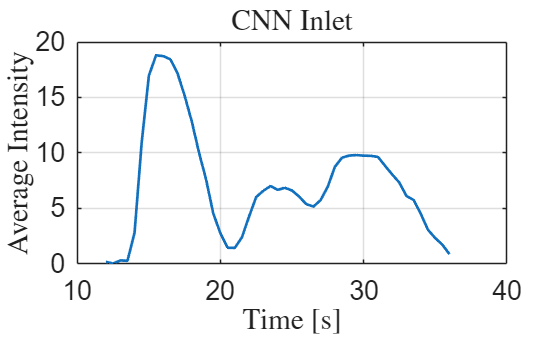


% Initialize an array to store the average intensity values
averageIntensities = zeros(1, length(segmentedFrames));

% Loop through each frame to calculate the average intensity along the line
for k = 1:length(segmentedFrames)
    frame = segmentedFrames{k};
    
    % Extract the pixel values along the line defined by xCoords and yCoords
    lineProfile = improfile(frame, xCoords, yCoords);
    
    % Calculate the average intensity for the pixels along the line
    averageIntensities(k) = mean(lineProfile(:));
end

%Swapping the values of averageIntensities around its maximum 
max_averageIntensities=max(averageIntensities);

averageIntensities_swap=-(averageIntensities-max_averageIntensities);
% Plot average intensities over time
timeVector = linspace(startTime, endTime, length(averageIntensities_swap)); % Create a time vector
figure; % Create a new figure window
plot(timeVector, averageIntensities_swap, 'LineWidth', 2); % Plot average intensities with blue line and circle markers
xlabel('Time [s]', 'Interpreter', 'latex'); % Label for X-axis
ylabel('Average Intensity', 'Interpreter', 'latex'); % Label for Y-axis
title('CNN Inlet', 'Interpreter', 'latex'); % Title of the plot
grid on; % Turn on the grid
set(gca, 'FontSize', fontsize); % Set font size for axes

### Reading at the Pipe 1, 2, and 3 outlets

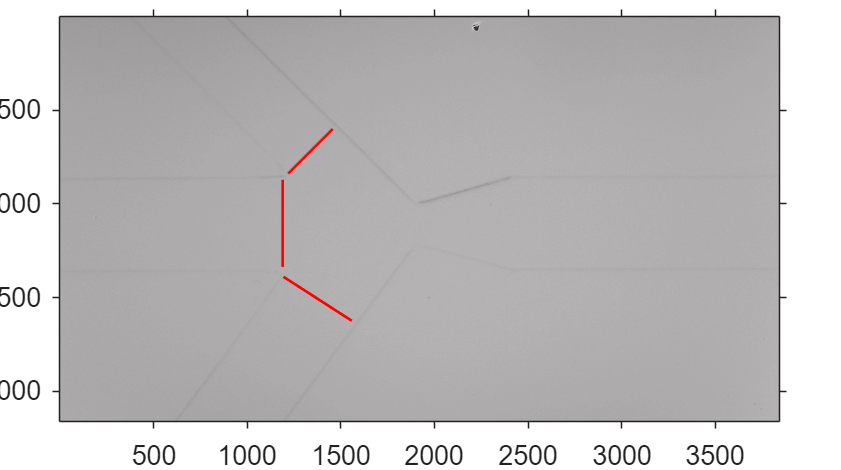

% Predefined coordinates for the line and pulse duration of 500ms
xCoords_pipe_1 = [1582, 1582]; % X coordinates
yCoords_pipe_1 = [1360, 921]; % Y coordinates
xCoords_pipe_2 = [1646, 1861]; % X coordinates
yCoords_pipe_2 = [887, 669]; % Y coordinates
xCoords_pipe_3 = [1621, 1945]; % X coordinates
yCoords_pipe_3 = [1399, 1639]; % Y coordinates


% Predefined coordinates for the line and pulse duration of 1 s
xCoords_pipe_1 = [1020, 1020]; % X coordinates
yCoords_pipe_1 = [1292, 871]; % Y coordinates
xCoords_pipe_2 = [1069, 1271]; % X coordinates
yCoords_pipe_2 = [798, 584]; % Y coordinates
xCoords_pipe_3 = [1057, 1401]; % X coordinates
yCoords_pipe_3 = [1324, 1538]; % Y coordinates

% Predefined coordinates for the line and pulse duration of 1.5 s
xCoords_pipe_1 = [1190, 1190]; % X coordinates
yCoords_pipe_1 = [1336, 871]; % Y coordinates
xCoords_pipe_2 = [1219, 1457]; % X coordinates
yCoords_pipe_2 = [838, 600]; % Y coordinates
xCoords_pipe_3 = [1194, 1559]; % X coordinates
yCoords_pipe_3 = [1389, 1624]; % Y coordinates

% Plot the first frame of segmentedFrames with axes
if ~isempty(segmentedFrames)
    figure; % Create a new figure window
    imshow(segmentedFrames{1}); % Display the first frame
    axis on; % Turn on the axes
    xlabel('Pixels (X)',Interpreter='latex'); % Label for X-axis
    ylabel('Pixels (Y)',Interpreter='latex'); % Label for Y-axis    
    
    % Hold the current plot to overlay the line
    hold on;
    plot(xCoords_pipe_1, yCoords_pipe_1, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    plot(xCoords_pipe_2, yCoords_pipe_2, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    plot(xCoords_pipe_3, yCoords_pipe_3, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    hold off;
    set(gca,"FontSize",fontsize)
else
    warning('No frames available to display.');
end


% Initialize an array to store the average intensity values
averageIntensities_pipe_1 = zeros(1, length(segmentedFrames));
averageIntensities_pipe_2 = zeros(1, length(segmentedFrames));
averageIntensities_pipe_3 = zeros(1, length(segmentedFrames));

% Loop through each frame to calculate the average intensity along the line
for k = 1:length(segmentedFrames)
    frame = segmentedFrames{k};
    
    % Extract the pixel values along the line defined by xCoords and yCoords
    lineProfile_pipe_1 = improfile(frame, xCoords_pipe_1, yCoords_pipe_1);
    lineProfile_pipe_2 = improfile(frame, xCoords_pipe_2, yCoords_pipe_2);
    lineProfile_pipe_3 = improfile(frame, xCoords_pipe_3, yCoords_pipe_3);
    
    % Calculate the average intensity for the pixels along the line
    averageIntensities_pipe_1(k) = mean(lineProfile_pipe_1(:));
    averageIntensities_pipe_2(k) = mean(lineProfile_pipe_2(:));
    averageIntensities_pipe_3(k) = mean(lineProfile_pipe_3(:));
end

%Swapping the values of averageIntensities around its maximum 
max_averageIntensities=max(averageIntensities_pipe_1);
averageIntensities_swap_pipe_1=-(averageIntensities_pipe_1-max_averageIntensities);

max_averageIntensities=max(averageIntensities_pipe_2);
averageIntensities_swap_pipe_2=-(averageIntensities_pipe_2-max_averageIntensities);

max_averageIntensities=max(averageIntensities_pipe_3);
averageIntensities_swap_pipe_3=-(averageIntensities_pipe_3-max_averageIntensities);


timeVector = linspace(startTime, endTime, length(averageIntensities_swap_pipe_1)); % Create a time vector

[~,idx]=max(averageIntensities_swap_pipe_1);
tau_1=timeVector(idx);
[~,idx]=max(averageIntensities_swap_pipe_2);
tau_2=timeVector(idx);
[~,idx]=max(averageIntensities_swap_pipe_3);
tau_3=timeVector(idx);

% Plot average intensities over time

figure; % Plotting the concentration with time
plot(timeVector, averageIntensities_swap_pipe_1, 'LineWidth', 2); hold on; % Plot average intensities with blue line and circle markers
plot(timeVector, averageIntensities_swap_pipe_2, 'LineWidth', 2); % Plot average intensities with blue line and circle markers
plot(timeVector, averageIntensities_swap_pipe_3, 'LineWidth', 2); % Plot average intensities with blue line and circle markers

% Plotting the maximum
max_intensity=max([max(averageIntensities_swap_pipe_1),max(averageIntensities_swap_pipe_2),max(averageIntensities_swap_pipe_3)])

max_intensity = 35.3469

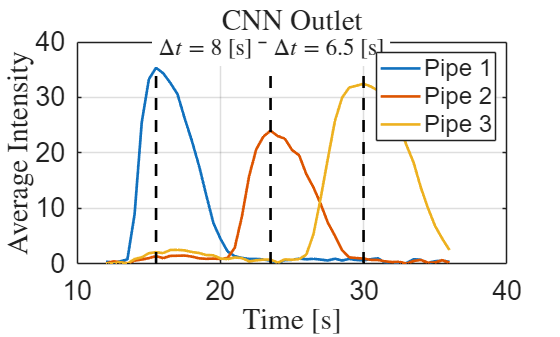

plot([tau_1 tau_1],[0 1.1*max_intensity],'--k',LineWidth=2)
plot([tau_2 tau_2],[0 1.1*max_intensity],'--k',LineWidth=2)
plot([tau_3 tau_3],[0 1.1*max_intensity],'--k',LineWidth=2)

text(tau_1,1.1*max_intensity,strcat('$\Delta t=',num2str(tau_2-tau_1),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w')
text(tau_2,1.1*max_intensity,strcat('$\Delta t=',num2str(tau_3-tau_2),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w')

xlabel('Time [s]', 'Interpreter', 'latex'); % Label for X-axis
ylabel('Average Intensity', 'Interpreter', 'latex'); % Label for Y-axis
title('CNN Outlet', 'Interpreter', 'latex'); % Title of the plot
legend("Pipe 1","Pipe 2","Pipe 3")
grid on; % Turn on the grid
set(gca, 'FontSize', fontsize); % Set font size for axes

#### Shifting Pipe 2 to the left

%Pipe 2
tau_2_new=(tau_1+tau_3)/2

tau_2_new = 22.7500

[~,idx]=max(averageIntensities_swap_pipe_2);
tau_2_experimental=timeVector(idx);
delta_tau_2=tau_2_new-tau_2_experimental

delta_tau_2 = -0.7500

%Calculating the new length
%coefficients
w_2=0.00015802;%as measured from the design in COMSOL_3D_CNN_Design_1_1.mph
L_2=0.014812*2;%as measured from the design in COMSOL_3D_CNN_Design_1_1.mph
geom_factor = 1 - 0.63*height_pipe/w_2;
p0_old=600;%pressure of previous simulations
K = p0_old * geom_factor * height_pipe^2 / (12*mu_Water);   % [m^2/s]
A = 1/K - 2*D_coeff / K^2;                               % [s/m^2]
%B = - height_pipe^2 / (100*D_coeff);                     % [s]
%tau_1_base = A .* L_1.^2 + B;   % [s]
arg = L_2.^2 + delta_tau_2./A;
L2_new  = sqrt(arg)

L2_new = 0.0288

Delta_L2 = L2_new - L_2

Delta_L2 = -7.8759e-04

# CAD design of the CNN-like structure

**Description:** This code evaluates the coordinates for the upper lines and lower lines for each pipe. As represented on Fig. 1, we define each pipe coordinates with points.

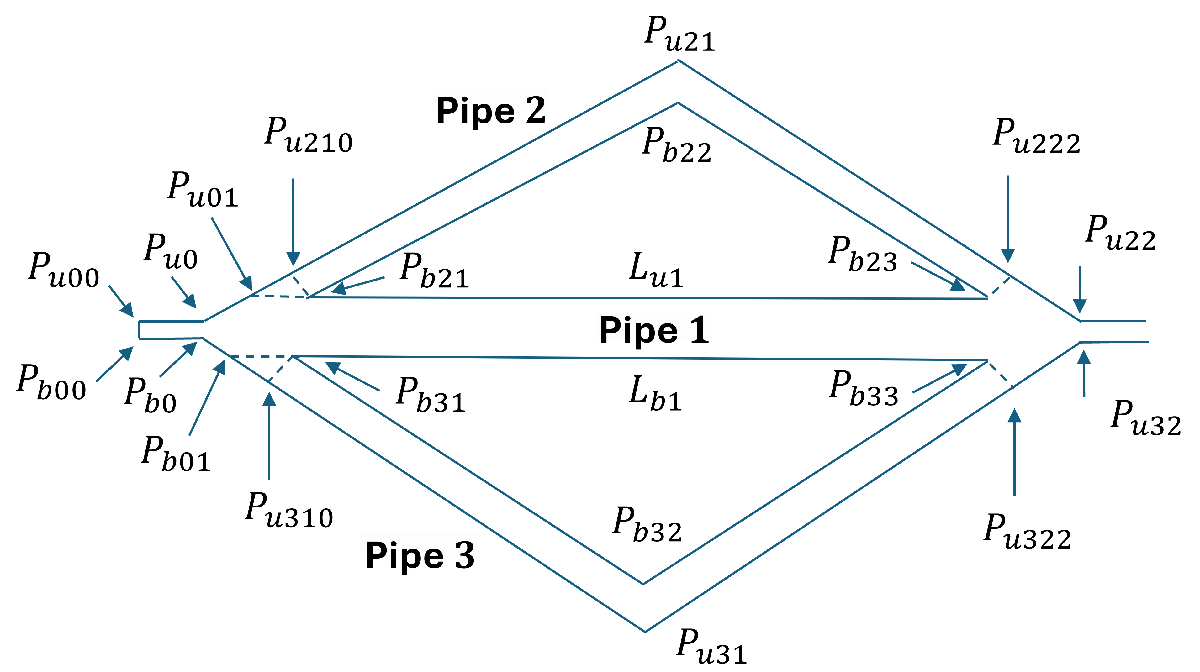

Figure 1: Reference points on the design.

## Asigning the new dimensions

L_1=21*1e-3;%as measured from the COMSOL file COMSOL_3D_CNN_Design_1_1.mph
L_2=L2_new;
L_3=17.539*2*1e-3;%as measured from the COMSOL file COMSOL_3D_CNN_Design_1_1.mph

w_1=0.00021198;%as measured from the COMSOL file COMSOL_3D_CNN_Design_1_1.mph
w_2=0.00015802;%as measured from the COMSOL file COMSOL_3D_CNN_Design_1_1.mph
w_3=0.00019947;%as measured from the COMSOL file COMSOL_3D_CNN_Design_1_1.mph

## Reference coordinates

%this reference coordinates are coming from the original CAD desing. This
%two points reference refer to the pipe just after the mixer on the
%transmitter side. See Fig. 1.
P_u0=[-42.36063776 1.75826183]*1e-3;
P_b0=[-42.36063776 1.65926683]*1e-3;
%width for the mixer pipe, this is taken from [4]
w_0=42.4264*1e-6;%P_u0(2)-P_b0(2);

fprintf('P_u0\n')

P_u0


fprintf('%.8f', P_u0(1)*1e3);   % fixed-point with 15 decimals

-42.36063776

fprintf('%.8f', P_u0(2)*1e3);   % fixed-point with 15 decimals

1.75826183


fprintf('P_b0\n')

P_b0


fprintf('%.8f', P_b0(1)*1e3);   % fixed-point with 15 decimals

-42.36063776

fprintf('%.8f', P_b0(2)*1e3);   % fixed-point with 15 decimals

1.65926683

## Restarting the reference coordinates

%length of the inlet
L_0=210e-6;

P_b00=[0 0];
P_u00=P_b00+[0 w_0]

P_u00 = 1.0e-04 *

         0    0.4243



fprintf('P_u00\n')

P_u00


fprintf('%.8f', P_u00(1)*1e3);   % fixed-point with 15 decimals

0.00000000

fprintf('%.8f', P_u00(2)*1e3);   % fixed-point with 15 decimals

0.04242640


fprintf('P_b0\n')

P_b0


fprintf('%.8f', P_b00(1)*1e3);   % fixed-point with 15 decimals

0.00000000

fprintf('%.8f', P_b00(2)*1e3);   % fixed-point with 15 decimals

0.00000000



P_b0=P_b00+[L_0 0];
P_u0=P_b0+[0 w_0];

fprintf('P_u0\n')

P_u0


fprintf('%.8f', P_u0(1)*1e3);   % fixed-point with 15 decimals

0.21000000

fprintf('%.8f', P_u0(2)*1e3);   % fixed-point with 15 decimals

0.04242640


fprintf('P_b0\n')

P_b0


fprintf('%.8f', P_b0(1)*1e3);   % fixed-point with 15 decimals

0.21000000

fprintf('%.8f', P_b0(2)*1e3);   % fixed-point with 15 decimals

0.00000000

## Pipe 2 coordinates

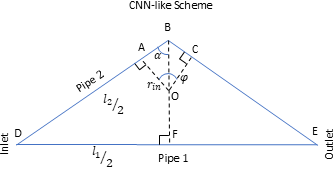

Figure 2: Reference angles within the pipe.

%heigth of the pipe
alpha=asin(L_1/L_2);
varphi_2=2*(pi-pi/2-alpha);
h_2=sqrt((L_2/2)^2-(L_1/2)^2);

P_u21=P_u0+[L_1/2 h_2];
fprintf('P_u21\n')

P_u21


fprintf('%.8f', P_u21(1)*1e3);   % fixed-point with 15 decimals

10.71000000

fprintf('%.8f', P_u21(2)*1e3);   % fixed-point with 15 decimals

9.92344895


%Calculating the point P_u01
%evaluating the line P_u0 to P_u21
m=(P_u21(2)-P_u0(2))/(P_u21(1)-P_u0(1))

m = 0.9410

b=P_u21(2)-m*P_u21(1)

b = -1.5519e-04

P_u01(2)=P_u0(2)+w_1/2;
P_u01(1)=(P_u01(2)-b)/m;
% fprintf('P_u01\n')
% fprintf('%.8f', P_u01(1)*1e3);   % fixed-point with 15 decimals
% fprintf('%.8f', P_u01(2)*1e3);   % fixed-point with 15 decimals

P_b21=P_u01+[w_2/h_2*L_2/2 0];
fprintf('P_b21\n')

P_b21


fprintf('%.8f', P_b21(1)*1e3);   % fixed-point with 15 decimals

0.55320938

fprintf('%.8f', P_b21(2)*1e3);   % fixed-point with 15 decimals

0.14841640


P_b22=P_u21+[0 -w_2/sin(alpha)];
fprintf('P_b22\n')

P_b22


fprintf('%.8f', P_b22(1)*1e3);   % fixed-point with 15 decimals

10.71000000

fprintf('%.8f', P_b22(2)*1e3);   % fixed-point with 15 decimals

9.70646185


L_u1=2*(P_b22(1)-P_b21(1));
P_b23=P_b21+[L_u1 0];
fprintf('P_b23\n')

P_b23


fprintf('%.8f', P_b23(1)*1e3);   % fixed-point with 15 decimals

20.86679062

fprintf('%.8f', P_b23(2)*1e3);   % fixed-point with 15 decimals

0.14841640


P_u22=P_u0+[L_1 0];
fprintf('P_u22\n')

P_u22


fprintf('%.8f', P_u22(1)*1e3);   % fixed-point with 15 decimals

21.21000000

fprintf('%.8f', P_u22(2)*1e3);   % fixed-point with 15 decimals

0.04242640


%Calculating the point P_u222
%evaluating the line P_u21 to P_u22
m=(P_u21(2)-P_u22(2))/(P_u21(1)-P_u22(1))

m = -0.9410

b=P_u21(2)-m*P_u21(1)

b = 0.0200

mA = -1/m; % slope of perpendicular to line P_u21 to Pu22 
P_u222(1) = (b - P_b23(2) + mA*P_b23(1)) / (mA - m);
P_u222(2) = m*P_u222(1) + b;

%Calculating the point P_u210
%evaluating the line P_u0 to P_u21
m=(P_u0(2)-P_u21(2))/(P_u0(1)-P_u21(1))

m = 0.9410

b=P_u0(2)-m*P_u0(1)

b = -1.5519e-04

mA = -1/m; % slope of perpendicular to line P_u21 to Pu22 
P_u210(1) = (b - P_b21(2) + mA*P_b21(1)) / (mA - m);
P_u210(2) = m*P_u210(1) + b;


## Pipe 3 coordinates

%heigth of the pipe
alpha=asin(L_1/L_3);
varphi_3=2*(pi-pi/2-alpha);
h_3=sqrt((L_3/2)^2-(L_1/2)^2);


P_u31=P_b0+[L_1/2 -h_3];
fprintf('P_u31\n')

P_u31


fprintf('%.8f', P_u31(1)*1e3);   % fixed-point with 15 decimals

10.71000000

fprintf('%.8f', P_u31(2)*1e3);   % fixed-point with 15 decimals

-14.04871955


%Calculating the point P_b01
%evaluating the line P_b0 to P_u31
m=(P_u31(2)-P_b0(2))/(P_u31(1)-P_b0(1))

m = -1.3380

b=P_u31(2)-m*P_u31(1)

b = 2.8097e-04

P_b01(2)=P_b0(2)-w_1/2;
P_b01(1)=(P_b01(2)-b)/m;
% fprintf('P_b01\n')
% fprintf('%.8f', P_b01(1)*1e3);   % fixed-point with 15 decimals
% fprintf('%.8f', P_b01(2)*1e3);   % fixed-point with 15 decimals

P_b31=P_b01+[w_3/h_3*L_3/2 0];
fprintf('P_b31\n')

P_b31


fprintf('%.8f', P_b31(1)*1e3);   % fixed-point with 15 decimals

0.53824339

fprintf('%.8f', P_b31(2)*1e3);   % fixed-point with 15 decimals

-0.10599000


P_b32=P_u31+[0 w_3/sin(alpha)];
fprintf('P_b32\n')

P_b32


fprintf('%.8f', P_b32(1)*1e3);   % fixed-point with 15 decimals

10.71000000

fprintf('%.8f', P_b32(2)*1e3);   % fixed-point with 15 decimals

-13.71552866


L_b1=2*(P_b32(1)-P_b31(1));
P_b33=P_b31+[L_b1 0];
fprintf('P_b33\n')

P_b33


fprintf('%.8f', P_b33(1)*1e3);   % fixed-point with 15 decimals

20.88175661

fprintf('%.8f', P_b33(2)*1e3);   % fixed-point with 15 decimals

-0.10599000


P_u32=P_b0+[L_1 0];
fprintf('P_u32\n')

P_u32


fprintf('%.8f', P_u32(1)*1e3);   % fixed-point with 15 decimals

21.21000000

fprintf('%.8f', P_u32(2)*1e3);   % fixed-point with 15 decimals

0.00000000


%Calculating the point P_u322
%evaluating the line P_u31 to Pu32
m=(P_u31(2)-P_u32(2))/(P_u31(1)-P_u32(1))

m = 1.3380

b=P_u31(2)-m*P_u31(1)

b = -0.0284

%evaluating the line P_u31 to P_u32
mA = -1/m; % slope of perpendicular to line P_u31 to Pu32 
P_u322(1) = (b - P_b33(2) + mA*P_b33(1)) / (mA - m);
P_u322(2) = m*P_u322(1) + b;

%Calculating the point P_u310
%evaluating the line P_b0 to P_u31
m=(P_b0(2)-P_u31(2))/(P_b0(1)-P_u31(1))

m = -1.3380

b=P_b0(2)-m*P_b0(1)

b = 2.8097e-04

%evaluating the line P_u31 to Pu32
mA = -1/m; % slope of perpendicular to line P_b0 to P_u31 
P_u310(1) = (b - P_b31(2) + mA*P_b31(1)) / (mA - m);
P_u310(2) = m*P_u310(1) + b;

## Pipe 1 coordinates

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end


P_b11=P_b0-[0 w_1/2];
fprintf('P_b11\n')

P_b11


fprintf('%.8f', P_b11(1)*1e3);   % fixed-point with 15 decimals

0.21000000

fprintf('%.8f', P_b11(2)*1e3);   % fixed-point with 15 decimals

-0.10599000


P_b12=P_b11+[L_1 0];
fprintf('P_b12\n')

P_b12


fprintf('%.8f', P_b12(1)*1e3);   % fixed-point with 15 decimals

21.21000000

fprintf('%.8f', P_b12(2)*1e3);   % fixed-point with 15 decimals

-0.10599000

## Outlet coordinates

outlet_length=L_0;
P_u11=P_u22+[outlet_length 0];
fprintf('P_u11\n')

P_u11


fprintf('%.8f', P_u11(1)*1e3);   % fixed-point with 15 decimals

21.42000000

fprintf('%.8f', P_u11(2)*1e3);   % fixed-point with 15 decimals

0.04242640


P_b11=P_u32+[outlet_length 0];
fprintf('P_b13\n')

P_b13


fprintf('%.8f', P_b11(1)*1e3);   % fixed-point with 15 decimals

21.42000000

fprintf('%.8f', P_b11(2)*1e3);   % fixed-point with 15 decimals

0.00000000

## Polygons

## saving the coordinates within a CSV file

%Upper polygon
% Stack all vertices row by row
coords = [P_b21; P_b22; P_b23; P_b21];
%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_upper_Phase_2.csv'); % build full path safely
writematrix(coords, outputFile);

%Bottom polygon
% Stack all vertices row by row
coords = [P_b31; P_b32; P_b33; P_b31];
%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_bottom_Phase_2.csv'); % build full path safely
writematrix(coords, outputFile);

%Outer polygon
% Stack all vertices row by row
coords = [P_u00; P_u0; P_u21; P_u22; P_u11; P_b11; P_u32; P_u31; P_b0; P_b00];
%saving in the CSV file
outputFile = fullfile(pwd, 'dataset', 'polygon_outer_Phase_2.csv'); % build full path safely
writematrix(coords, outputFile);

#### Saving variables in Matlab

T = readtable('parameters_2D.csv', 'TextType','string');

%height of Pipes 
newRow = makeRow(height_pipe, "height of pipes", "um", 1e6);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(height_pipe)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile);

%Length Pipe 1
newRow = makeRow(L_1, "Length of Pipe 1", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(L_1)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 1
newRow = makeRow(w_1, "Width of Pipe 1", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_1)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);


%Length Pipe 2
newRow = makeRow(L_2, "Length of Pipe 2", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(L_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 2
newRow = makeRow(w_2, "Width of Pipe 2", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);


%Length Pipe3
newRow = makeRow(L_3, "Length of Pipe 3", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(L_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 3
newRow = makeRow(w_3, "Width of Pipe 3", "mm", 1e3);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);


%P_b23
P_b23_x=P_b23(1)

P_b23_x = 0.0209

newRow = makeRow(P_b23_x, "x-Coordinates for P_b23", "m",1);
%Delete any existing row with the same Name
T(T.Variables== string(getVarName(P_b23_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_b23_y=P_b23(2)

P_b23_y = 1.4842e-04

newRow = makeRow(P_b23_y, "y-Coordinates for P_b23", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b23_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_b33
P_b33_x=P_b33(1)

P_b33_x = 0.0209

newRow = makeRow(P_b33_x, "x-Coordinates for P_b33", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b33_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_b33_y=P_b33(2)

P_b33_y = -1.0599e-04

newRow = makeRow(P_b33_y, "y-Coordinates for P_b33", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b33_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u222
P_u222_x=P_u222(1)

P_u222_x = 0.0210

newRow = makeRow(P_u222_x, "x-Coordinates for P_u222", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u222_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u222_y=P_u222(2)

P_u222_y = 2.6349e-04

newRow = makeRow(P_u222_y, "y-Coordinates for P_u222", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u222_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u322
P_u322_x=P_u322(1)

P_u322_x = 0.0210

newRow = makeRow(P_u322_x, "x-Coordinates for P_u322", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u322_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u322_y=P_u322(2)

P_u322_y = -2.2541e-04

newRow = makeRow(P_u322_y, "y-Coordinates for P_u322", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u322_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u210
P_u210_x=P_u210(1)

P_u210_x = 4.4492e-04

newRow = makeRow(P_u210_x, "x-Coordinates for P_u210", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u210_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u210_y=P_u210(2)

P_u210_y = 2.6349e-04

newRow = makeRow(P_u210_y, "y-Coordinates for P_u210", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u210_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_b21
P_b21_x=P_b21(1)

P_b21_x = 5.5321e-04

newRow = makeRow(P_b21_x, "x-Coordinates for P_b21", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b21_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_b21_y=P_b21(2)

P_b21_y = 1.4842e-04

newRow = makeRow(P_b21_y, "y-Coordinates for P_b21", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b21_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_b31
P_b31_x=P_b31(1)

P_b31_x = 5.3824e-04

newRow = makeRow(P_b31_x, "x-Coordinates for P_b31", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b31_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_b31_y=P_b31(2)

P_b31_y = -1.0599e-04

newRow = makeRow(P_b31_y, "y-Coordinates for P_b31", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_b31_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u310
P_u310_x=P_u310(1)

P_u310_x = 3.7847e-04

newRow = makeRow(P_u310_x, "x-Coordinates for P_u310", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u310_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u310_y=P_u310(2)

P_u310_y = -2.2541e-04

newRow = makeRow(P_u310_y, "y-Coordinates for P_u310", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u310_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%P_u31
P_u31_x=P_u31(1)

P_u31_x = 0.0107

newRow = makeRow(P_u31_x, "x-Coordinates for P_u31", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u31_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

P_u31_y=P_u31(2)

P_u31_y = -0.0140

newRow = makeRow(P_u31_y, "y-Coordinates for P_u31", "m",1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(P_u31_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%Length Pipe 2
newRow = makeRow(L_2, "Length of Pipe 2", "m", 1);
%Delete any existing row with the same Name

T(T.Variables == string(getVarName(L_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 2
newRow = makeRow(w_2, "width of Pipe 2", "m", 1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%Angle Pipe 2
newRow = makeRow(varphi_2, "Angle of Pipe 2", "rad", 1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(varphi_2)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%Length Pipe 3
newRow = makeRow(L_3, "Length of Pipe 3", "m", 1);
%Delete any existing row with the same Name

T(T.Variables == string(getVarName(L_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile);

%Width Pipe 3
newRow = makeRow(w_3, "width of Pipe 3", "m", 1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(w_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

%Angle Pipe 2
newRow = makeRow(varphi_3, "Angle of Pipe 3", "rad", 1);
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(varphi_3)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

### Normal vectors to defined planes

%vector normal ot the input plane defined by the three points 
% Define three points (row vectors)
P1 = [P_u310_x, P_u310_y, 0];
P2 = [P_u310_x, P_u310_y, height_pipe];
P3 = [P_b31_x, P_b31_y, 0];

% Vectors lying in the plane
v1 = P2 - P1;
v2 = P3 - P1;

% Cross product -> normal vector
n = cross(v1, v2);

% Normalize -> orthonormal vector
n_Pipe_3_inlet = n / norm(n);

disp('The orthonormal vector to the plane is:');

The orthonormal vector to the plane is:


disp(n_Pipe_3_inlet);

   -0.5987    0.8010         0




%n_Pipe_3_inlet
n_Pipe_3_inlet_x=n_Pipe_3_inlet(1)

n_Pipe_3_inlet_x = -0.5987

newRow = makeRow_no_unit(n_Pipe_3_inlet_x, "x-Coordinates for n_Pipe_3_inlet");
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(n_Pipe_3_inlet_x)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

n_Pipe_3_inlet_y=n_Pipe_3_inlet(2)

n_Pipe_3_inlet_y = 0.8010

newRow = makeRow_no_unit(n_Pipe_3_inlet_y, "y-Coordinates for n_Pipe_3_inlet");
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(n_Pipe_3_inlet_y)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

n_Pipe_3_inlet_z=n_Pipe_3_inlet(3)

n_Pipe_3_inlet_z = 0

newRow = makeRow_no_unit(n_Pipe_3_inlet_z, "y-Coordinates for n_Pipe_3_inlet");
%Delete any existing row with the same Name
T(T.Variables == string(getVarName(n_Pipe_3_inlet_z)), :) = [];
%assign the same table names
newRow.Properties.VariableNames=T.Properties.VariableNames;
%Append to the CSV
T = [T; newRow];
outputFile = fullfile(pwd, 'dataset', 'parameters_2D_Phase_2.csv'); % build full path safely
writetable(T, outputFile, 'WriteVariableNames', false);

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end

function trow = makeRow(var, description, unit, scale)
    name = inputname(1);
    valStr = sprintf('%g[%s]', var*scale, unit);
    trow = table(string(name), string(valStr), string(description), ...
                 'VariableNames', {'Name','Value','Description'});
end

function trow = makeRow_no_unit(var, description)
    name = inputname(1);
    valStr = sprintf('%g', var);
    trow = table(string(name), string(valStr), string(description), ...
                 'VariableNames', {'Name','Value','Description'});
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, “Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section,” *Mathematical and Computer Modelling*, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: [10.1016/j.mcm.2006.11.029](https://doi.org/10.1016/j.mcm.2006.11.029).  